# Exploring the impact of mismatch between the "true" biology and "assumed" stock dynamics for harvested stocks

### V2 has harvesting added!

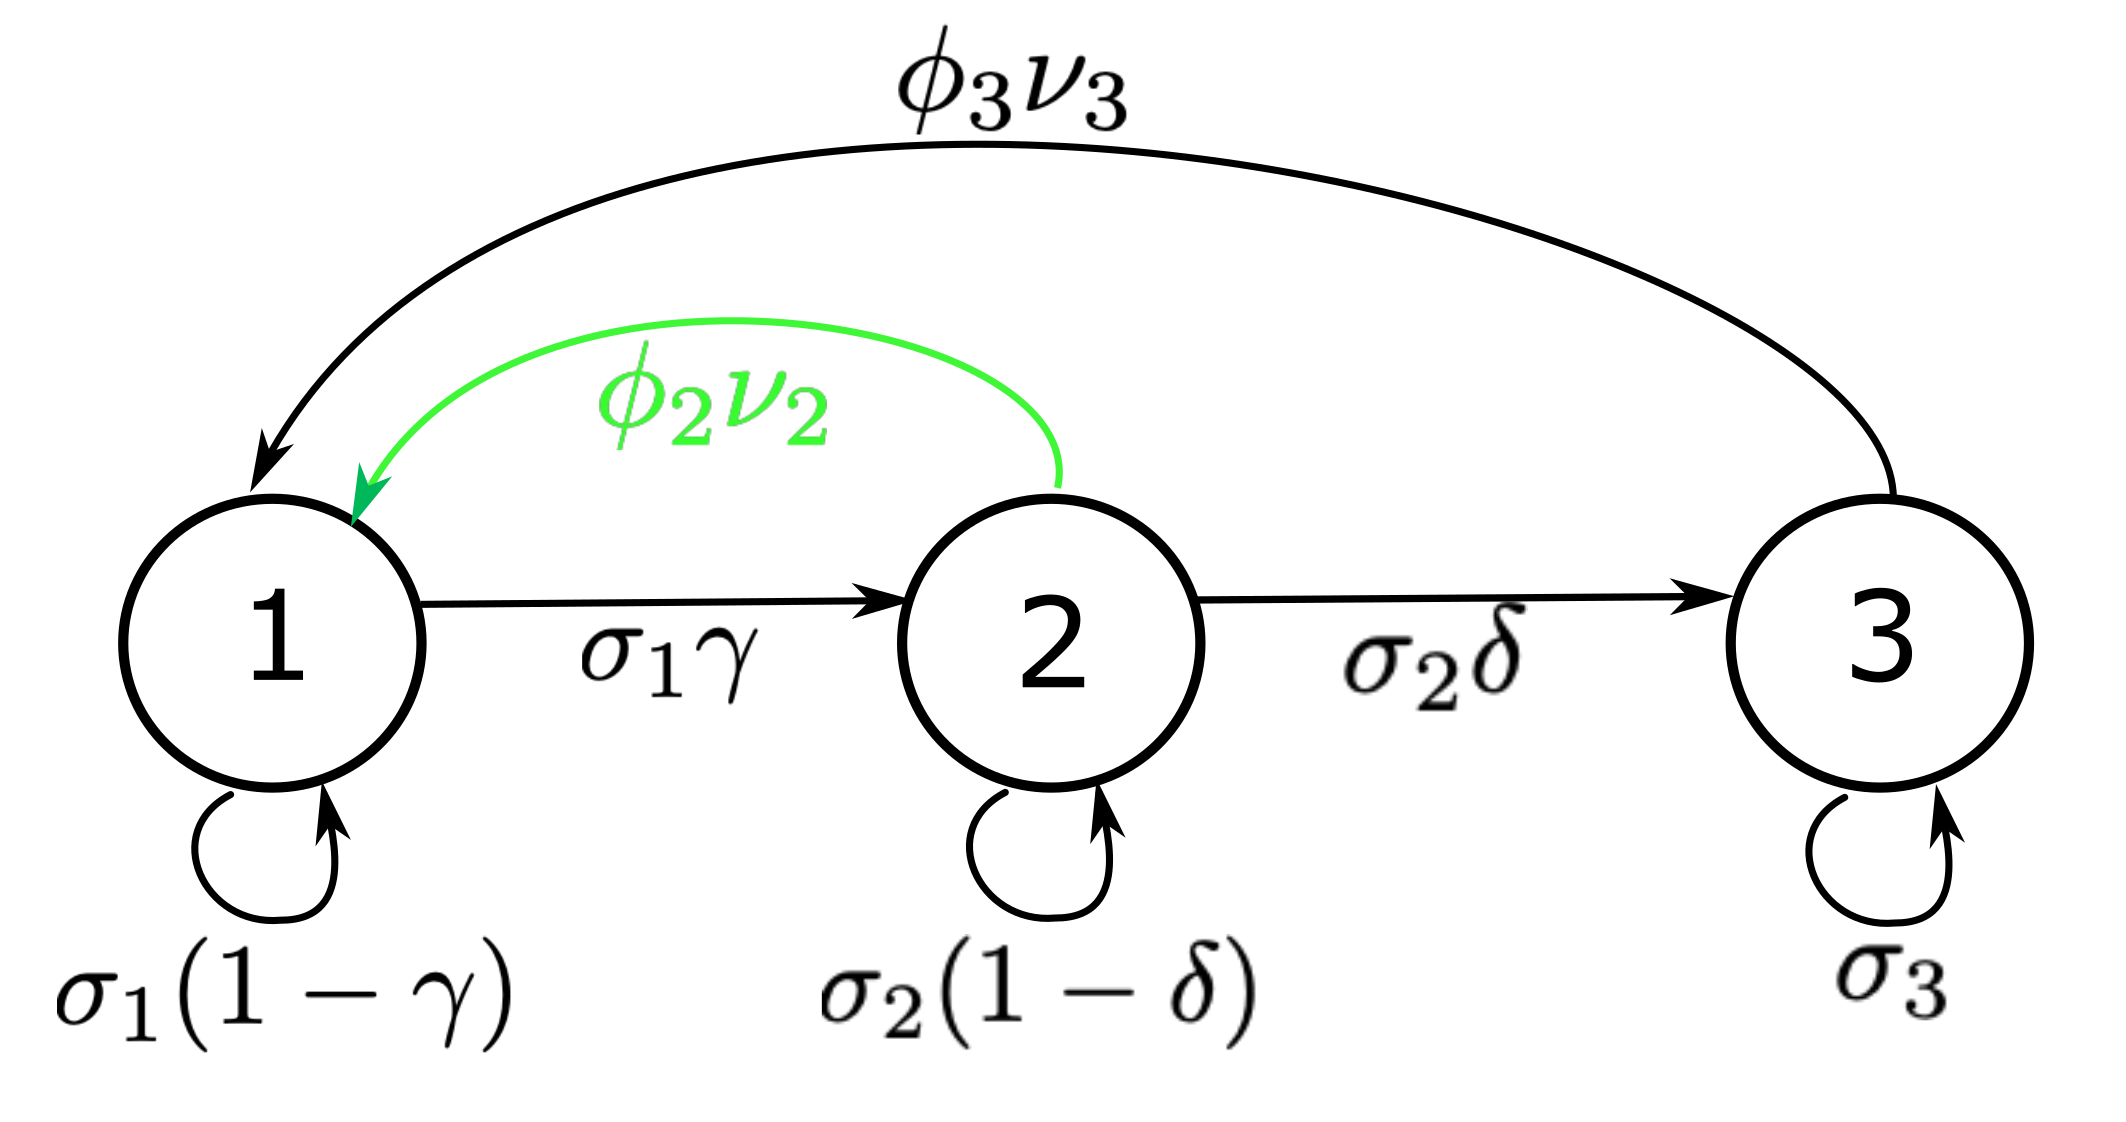

In this model, we use a stage-structured approach, where $\gamma
$ and $\delta$ are the probability of advancing to the next stage (the average time spent in each stage is $1/\gamma
$ and $1/\delta
$). The "true" biology of the population includes reproduction by individuals in stage 2 (the arrow in green), but the "assumed" model used by managers includes reproduction only by individuals in stage 3. 

We would like to understand how a harvesting strategy selected using the "assumed" model will impact on the "true" population.

Note that this life cycle graph does not represent the density dependent processes that operate in this population. We have implemented density dependence by making $\phi_2$ and $\phi_3$ functions of the abundance of individuals in stage 2 and 3. We have used a Beverton-Holt density dependence:

$\phi_3 = \frac{\phi_3^{max}\nu_3}{1+\frac{n_a}{\alpha_3}}$, where $n_a = n_2+wn_3$ and w is a linear weighting parameter for the relative influence on the density dependence of individuals in stages 2 and 3.

## Set the parameters

#### First, we'll set the parameters that are the same between both models: 

We assume that the observations of abundance, survival, and stage duration are all accurate, so these parameters are the same between both the "assumed" and "true" models. 

sigma_1 = 0.2;
sigma_2 = 0.4;
sigma_3 = 0.8;
gamma = 0.33;
delta = 0.2;

#### Next, we'll set the parameters that differ between the two models: 

If we hope to find a coincident equilibrium between the two models (one with reproduction only in stage 3, and the other with reproduction in stages 2 and 3), then their reproductive parameters must differ. We refer to the parameters in the "true" model using a tilde, and those in the "assumed" model using a hat.

"True" model:

phi_2_tilde = 74920;
nu_2_tilde = 0.05;
alpha_2_tilde = 1000;%0.8;
phi_3_tilde = 1000000;
nu_3_tilde = 0.05;
alpha_3_tilde = 1000; %0.8;
w_tilde = 3;

"Assumed" model:

phi_3_hat = 1000000;
nu_3_hat = 0.05;
alpha_3_hat = 1000;%0.8;
w_hat = 3;

## Numerically Finding a Coincident Equilibrium

It's been hard to find an analytical expression for the coincident equilibrium. Instead, we can solve for it numerically. 

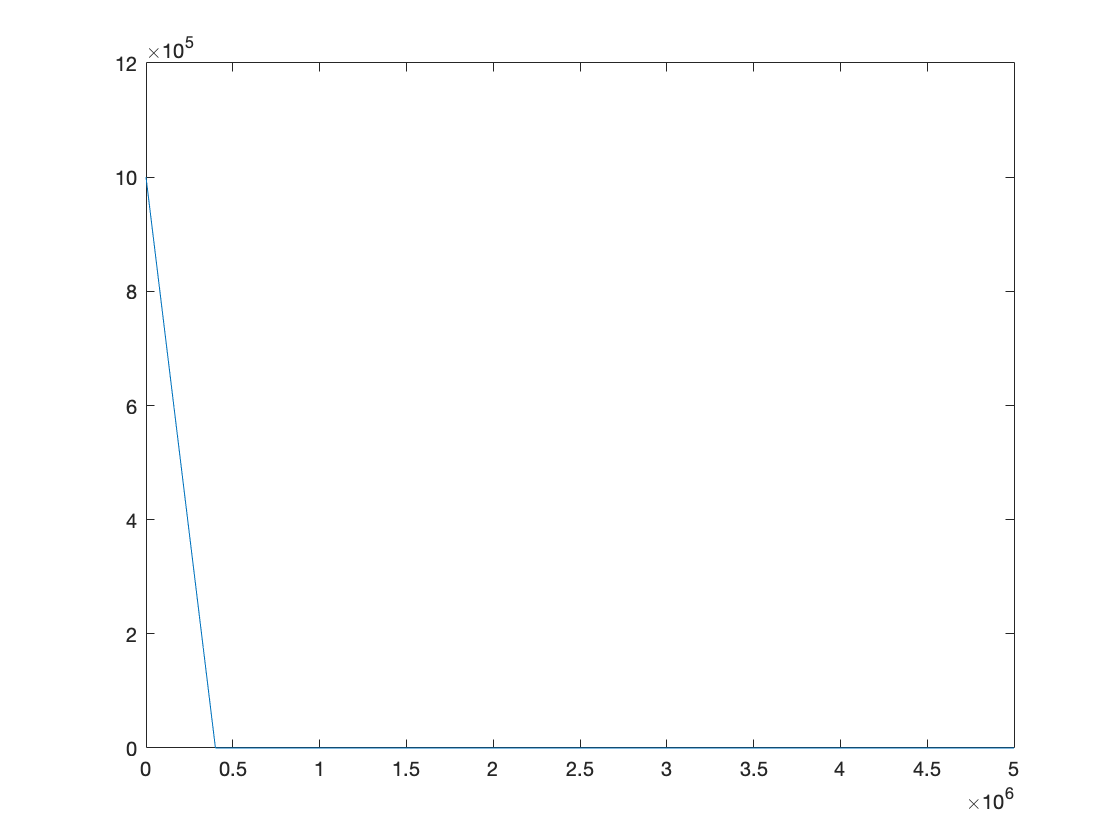

% iterate across values of phi_3, given a value of phi_2:
phi_2_vals = 0:1e2:5e6;

% equilibrium of the assumed model: 
a = sigma_1*gamma/(1-sigma_2*(1-delta));
b = sigma_2*delta/(1-sigma_3);
nhat1_eq_expected = alpha_3_hat/(a*(1+w_hat*b))*(phi_3_hat*nu_3_hat*a*b/(1-sigma_1*(1-gamma))-1);
nhat_eq_expected = [nhat1_eq_expected, a*nhat1_eq_expected, a*b*nhat1_eq_expected];

% output: phi_3 required for coincident equilibrium between true and
% expected models
phi_3_vals = zeros([1, length(phi_2_vals)]);

for j = 1:length(phi_2_vals)
    phi_2_tilde = phi_2_vals(j);
    
    findSSDj = @(phi_3_tilde) findSSD(phi_2_tilde, phi_3_tilde);
    
    phi_3_vals(j) = fminbnd(findSSDj,0, 5e6);

end

% plot phi_2 vs phi_3
figure
plot(phi_2_vals, phi_3_vals)


phi_3_hat

phi_3_hat = 1000000

phi_3_vals(1)

ans = 1.0000e+06

## Solve for F_MSY in the assumed model:

F_MSY is the rate of fishing mortality that maximizes sustainable yield. Since we are at equilibrium, the yield is equal to the biomass times the fishing mortality rate (Y = F * n3). 

So, we numerically find the fishing mortality that maximizes sustainable yield. 

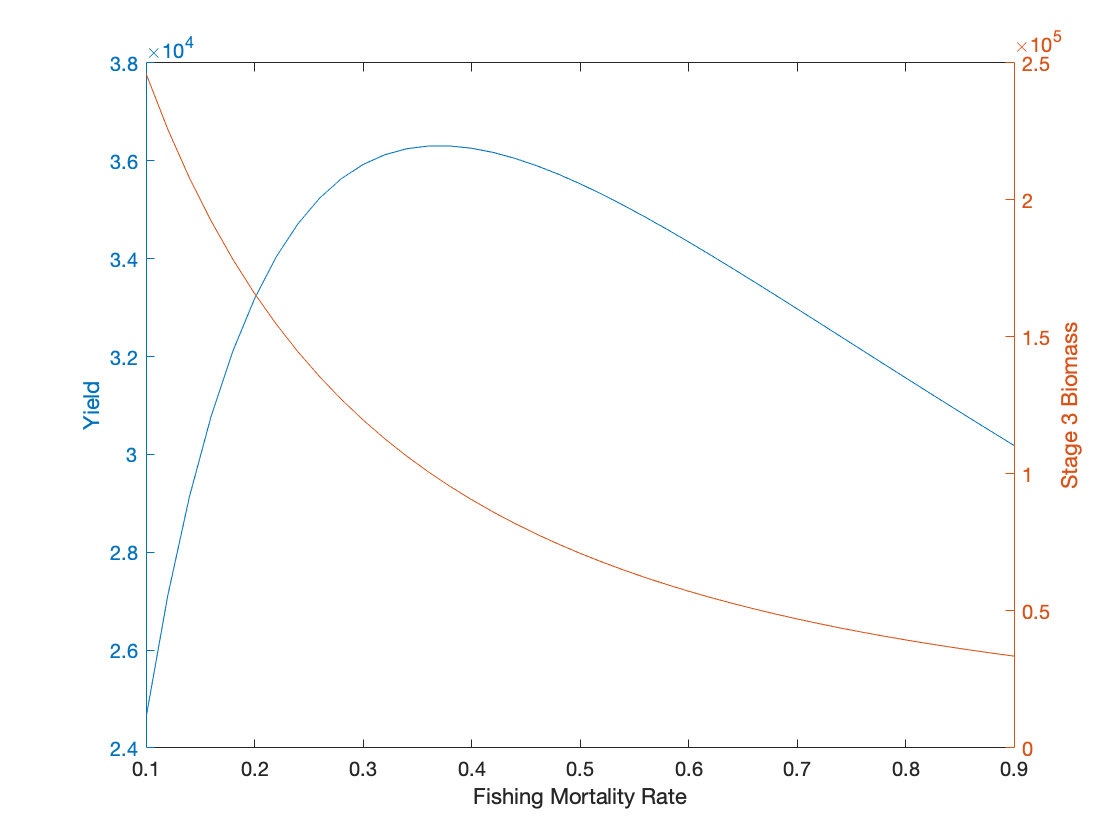

% Values of fishing mortality to test:
F = 0.1:0.02:0.9;
Y = zeros(1, length(F));
n3_hat_eq = zeros(1, length(F));

% set the number of timesteps:
tmax = 500;

for j=1:length(F)

    % initialize ntilde vectors:
    n1_hat = zeros(1,tmax);
    n2_hat = zeros(1,tmax);
    n3_hat = zeros(1,tmax);
    
    % set the initial condition:
    n1_hat(1) = 10;
    n2_hat(1) = 10;
    n3_hat(1) = 10;
    
    % run the model for tmax steps:
    for i = 2:tmax
        na = n2_hat(i-1)+w_hat*n3_hat(i-1);
        n1_hat(i) = phi_3_hat*nu_3_hat/(1+na/alpha_3_hat)*n3_hat(i-1) + sigma_1*(1-gamma)*n1_hat(i-1);
        n2_hat(i) = sigma_1*gamma*n1_hat(i-1) + sigma_2*(1-delta)*n2_hat(i-1);
        n3_hat(i) = sigma_2*delta*n2_hat(i-1) + sigma_3*n3_hat(i-1)*(1-F(j));
    end
    
    n3_hat_eq(j) = n3_hat(tmax);
    Y(j) = n3_hat(tmax)*F(j);
    
end


% make the plot:
figure
yyaxis left
plot(F, Y)
xlabel("Fishing Mortality Rate")
ylabel("Yield")
yyaxis right
plot(F, n3_hat_eq)
ylabel("Stage 3 Biomass")

disp(['MSY is ', num2str(max(Y))])

MSY is 36304.3541


disp(['F_MSY is ', num2str(F(Y==max(Y)))])

F_MSY is 0.38


## Solve for F_MSY in the true model:

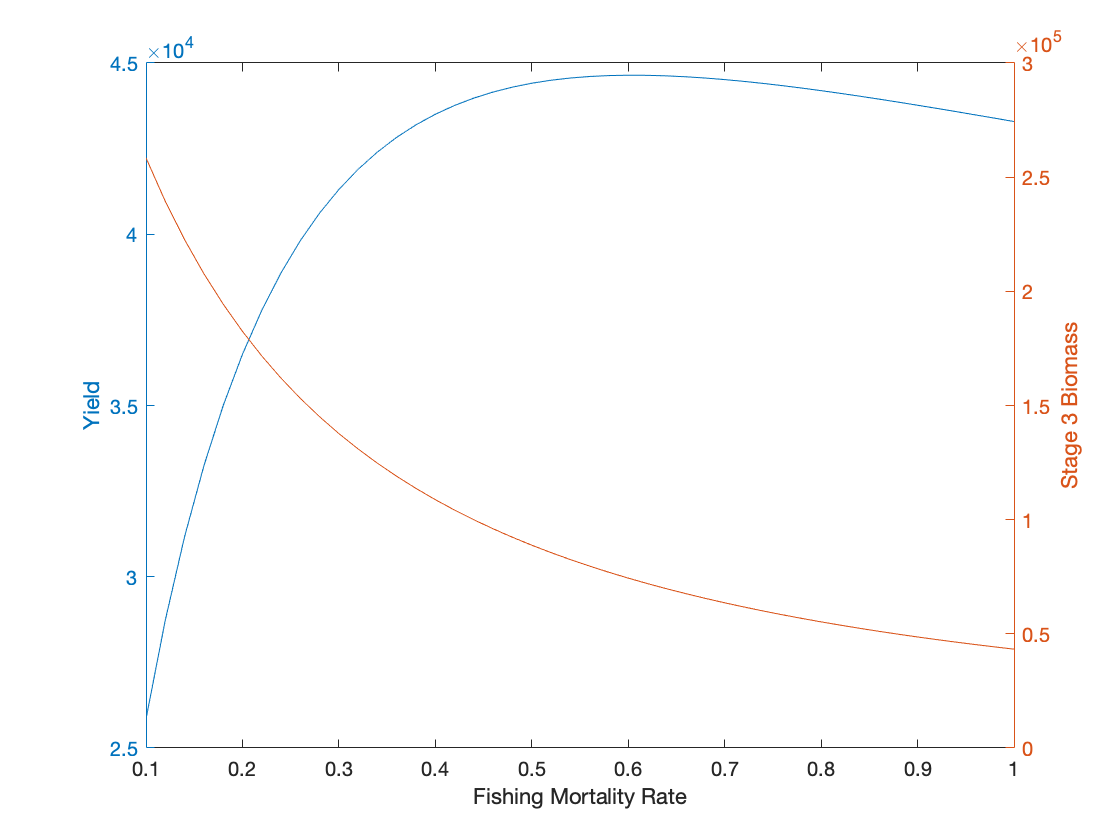

% Values of fishing mortality to test:
F = 0.1:0.02:1;
Y = zeros(1, length(F));
n3_tilde_eq = zeros(1, length(F));

% set the number of timesteps:
tmax = 500;

% use the phi_2_tilde tradeoff with phi_3_tilde:
phi_2_tilde = phi_2_vals(500);
phi_3_tilde = phi_3_vals(500);

for j=1:length(F)

    % initialize ntilde vectors:
    n1_tilde = zeros(1,tmax);
    n2_tilde = zeros(1,tmax);
    n3_tilde = zeros(1,tmax);
    
    % set the initial condition:
    n1_tilde(1) = 10;
    n2_tilde(1) = 10;
    n3_tilde(1) = 10;
    
    % run the model for tmax steps:
    for i = 2:tmax
        na = n2_tilde(i-1)+w_tilde*n3_tilde(i-1);
        n1_tilde(i) = phi_2_tilde*nu_2_tilde/(1+na/alpha_2_tilde)*n2_tilde(i-1) + phi_3_tilde*nu_3_tilde/(1+na/alpha_3_tilde)*n3_tilde(i-1) + sigma_1*(1-gamma)*n1_tilde(i-1);
        n2_tilde(i) = sigma_1*gamma*n1_tilde(i-1) + sigma_2*(1-delta)*n2_tilde(i-1);
        n3_tilde(i) = sigma_2*delta*n2_tilde(i-1) + sigma_3*n3_tilde(i-1)*(1-F(j));
    end
    
    n3_tilde_eq(j) = n3_tilde(tmax);
    Y(j) = n3_tilde(tmax)*F(j);
    
end


% make the plot:
figure
yyaxis left
plot(F, Y)
xlabel("Fishing Mortality Rate")
ylabel("Yield")
yyaxis right
plot(F, n3_tilde_eq)
ylabel("Stage 3 Biomass")

disp(['MSY is ', num2str(max(Y))])

MSY is 44643.3963


disp(['F_MSY is ', num2str(F(Y==max(Y)))])

F_MSY is 0.6
